expmt.data.time

ans =   4807×1 RawDataField array with properties:

          raw: [4807×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/14-08/geo-agar-short-6/08-16-2021-17-12-35__Basic_Tracking_1-1_Day1/raw_data/08-16-2021-17-12-35__time.bin'
          fID: 4
          dim: [4807 1]
    precision: 'single'


reset(expmt.data.time)

ans =   4807×1 RawDataField array with properties:

          raw: [4807×1 RawDataMap]
         path: 'C:/Users/Jefferis Group/Documents/GitHub/margo_data/14-08/geo-agar-short-6/08-16-2021-17-12-35__Basic_Tracking_1-1_Day1/raw_data/08-16-2021-17-12-35__time.bin'
          fID: 4
          dim: [4807 1]
    precision: 'single'


isattached(expmt.data.time)

ans = logical
   1


interframe_interval = expmt.data.time.raw();
t_elapsed = cumsum(interframe_interval);
% read all centroid data from file
reset(expmt.data.centroid);
centroids = expmt.data.centroid.raw();
a = expmt.meta.roi

a = struct with fields:
           mode: 'grid'
          shape: {'Quadrilateral'}
            vec: [1×4×2 double]
            row: 1
            col: 1
           grid: 1
        corners: [3.1611 2.0967 1.0208e+03 1.0197e+03]
         bounds: [3.1611 2.0967 1.0176e+03 1.0176e+03]
        centers: [511.9678 510.9033]
    orientation: 0
          tform: {[]}
             im: [1024×1024 uint8]
              n: 1
         pixIdx: {[1038361×1 double]}
           mask: [1024×1024 logical]
     num_traces: 5
       cam_dist: 722.5724


xcentre = (a.centers(1,1))

xcentre = 511.9678

ycentre = (a.centers(1,2))

ycentre = 510.9033

out = num2cell(centroids, [1 2]); %split into cell array keeping dimensions 1 and 2 together
out = vertcat(out{:})

out = 24035×2 single matrix
	1.0e+03 *

       NaN       NaN
       NaN       NaN
       NaN       NaN
       NaN       NaN
    0.3783    0.2726
    0.3757    0.2671
    0.3696    0.2594
    0.3629    0.2497
    0.3568    0.2394
    0.3496    0.2257



x = out(:, 1);
y = out(:, 2);

out(x>xcentre & y>ycentre,3) = 1;
out(x<xcentre & y>ycentre,3) = 2;
out(x<xcentre & y<ycentre,3) = 3;
out(x>xcentre & y<ycentre,3) = 4;

x = out(:, 1);
y = out(:, 2);

out(x>xcentre+50 & y>ycentre+50,3) = 1;
out(x<xcentre-50 & y>ycentre+50,3) = 2;
out(x<xcentre-50 & y<ycentre-50,3) = 3;
out(x>xcentre+50 & y<ycentre-50,3) = 4;

out(x>xcentre-50 & x<xcentre+50,3) = 0; 
out(y>ycentre-50 & y<ycentre+50,3) = 0;

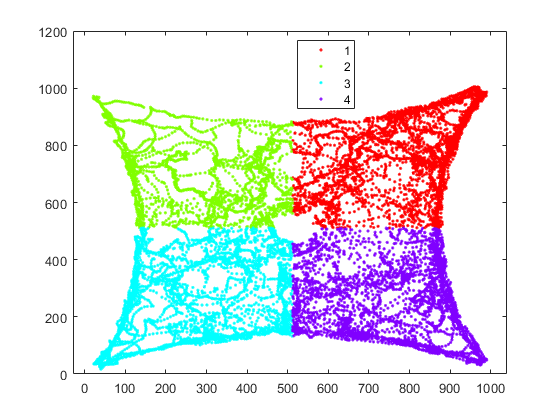

%Convert to table
T = array2table(out);

%Remove NaNs
T=T(~any(ismissing(T),2),:);

gscatter(T.out1, T.out2, T.out3)

%Attraction index for each quarter, without cross
GC = groupcounts(T,'out3');
C1 = table2array(GC(1,2));
C2 = table2array(GC(2,2));
C3 = table2array(GC(3,2));
C4 = table2array(GC(4,2));
AI1 = (C1-(C2+C3+C4)/3)/(C1+(C2+C3+C4)/3);
AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
AI3 = (C3-(C2+C1+C4)/3)/(C3+(C2+C1+C4)/3);
AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);

%Attraction index for each quarter with cross
GC = groupcounts(T,'out3');
C1 = table2array(GC(2,2));
C2 = table2array(GC(3,2));
C3 = table2array(GC(4,2));
C4 = table2array(GC(5,2));

Row index exceeds table dimensions.

AI1 = (C1-(C2+C3+C4)/3)/(C1+(C2+C3+C4)/3);
AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
AI3 = (C3-(C2+C1+C4)/3)/(C3+(C2+C1+C4)/3);
AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);


GC = groupcounts(T,'out3');
C1 = 0;
C2 = table2array(GC(2,2));
C3 = table2array(GC(3,2));
C4 = table2array(GC(4,2));
AI1 = (C1-(C2+C3+C4)/3)/(C1+(C2+C3+C4)/3);
AI2 = (C2-(C1+C3+C4)/3)/(C2+(C1+C3+C4)/3);
AI3 = (C3-(C2+C1+C4)/3)/(C3+(C2+C1+C4)/3);
AI4 = (C4-(C2+C3+C1)/3)/(C4+(C2+C3+C1)/3);


